# Fast Fourier Tansform Alogorithem 

### Fourier Transform : 

The Fourier transform is a mathematical formula that relates a signal sampled in time or space to the same signal sampled in frequency. In signal processing, the Fourier transform can reveal important characteristics of a signal, namely, its frequency components.

The Fourier transform is defined for a vector *x* with *n* uniformly sampled points by


$$y_{k+1}=\sum_{j=0}^{n-1}w^{jk}x_{j+1}$$


*ω*=*e*−2*π**i*/*n* is one of *n* complex roots of unity where *i* is the imaginary unit. For *x* and *y*, the indices *j* and *k* range from 0 to *n*−1.

The `fft` function in MATLAB® uses a fast Fourier transform algorithm to compute the Fourier transform of data. Consider a sinusoidal signal `x` that is a function of time `t` with frequency components of 15 Hz and 20 Hz. Use a time vector sampled in increments of 150 of a second over a period of 10 seconds.

t = 0:1/50:10-1/50                     

t =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


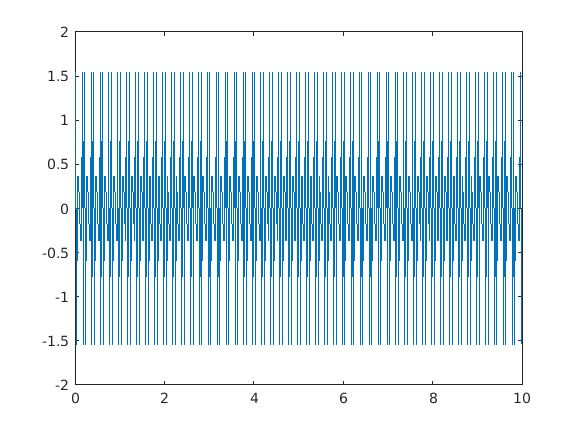

x = sin(2*pi*15*t) + sin(2*pi*20*t);
plot(t,x)

Compute the Fourier transform of the signal, and create the vector `f` that corresponds to the signal's sampling in frequency space.

y = fft(x);     
f = (0:length(y)-1)*50/length(y);

When you plot the magnitude of the signal as a function of frequency, the spikes in magnitude correspond to the signal's frequency components of 15 Hz and 20 Hz.

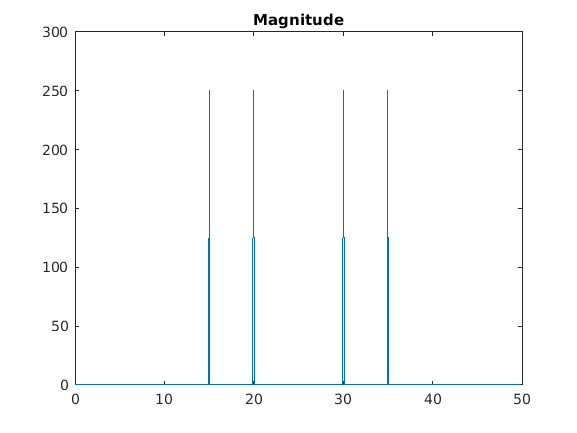

plot(f,abs(y))
title('Magnitude')

The transform also produces a mirror copy of the spikes, which correspond to the signal's negative frequencies. To better visualize this periodicity, you can use the `fftshift` function, which performs a zero-centered, circular shift on the transform.

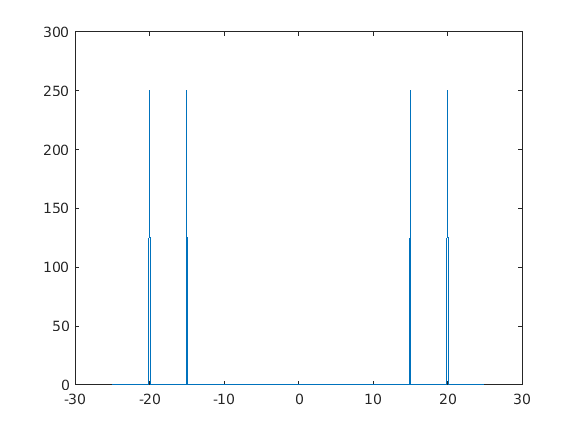

n = length(x);                         
fshift = (-n/2:n/2-1)*(50/n);
yshift = fftshift(y);
plot(fshift,abs(yshift))